# Senzory a Měření - protokol 1 - měření s ADC

Vypracoval **Vojtěch Michal** 11. března 2021, měření provedeno na dálku dne 4. 3. 2021.

### 1) Successive approximation register ADC

Převodník s postupnou aproximací. Měření provedeno na osmibitovém převodníku WSH570, full scale +/- 10 V (rozlišení 78 mV na 1 LSB). Výstupní slovo je generováno po seriové lince v kódu s posunutou nulou (-10V ~ výstpní slovo 0, 0V ~ výstupní slovo 127, 10V ~ výstupní slovo 255). Chronologicky první platný bit je MSB, binárním vyhledáváním se převodník následně snaží ustálit hodnoty ostatních bitů. Ilustrace průběhu ustalování je vidět na následujícím grafu, který ukazuje postupnou konvergenci rozdílu napětí na vstupech komparátoru k nule (DAC generuje napětí víc a víc podobné napětí měřenému).

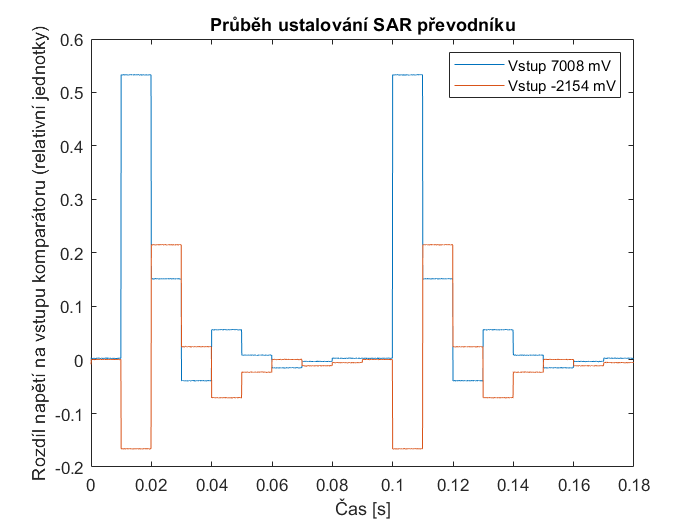

%Vybereme nějaké dva (dostatečně odlišné) průběhy
dataA = readmatrix('data/SAR/SAR_1V_+7008mV.csv');
dataB = readmatrix('data/SAR/SAR_1V_-2154mV.csv');
twoPeriods = 1 : 1800; %Nepotřebujeme všech 20k vzorků, stačí pár period pro názornost
columnCount = size(dataA, 2); %počet sloupců v datech
time = dataA(twoPeriods, size(dataA, 2)); %časová osa prováděných měření
plot(time, dataA(twoPeriods,columnCount - 1));
hold on
plot(time, dataB(twoPeriods,columnCount - 1));
title('Průběh ustalování SAR převodníku')
legend('Vstup 7008 mV', 'Vstup -2154 mV', 'Location', 'northeast')
xlabel('Čas [s]')
ylabel('Rozdíl napětí na vstupu komparátoru (relativní jednotky)')

Výsledek převodu je hotov, když nabyde bit *STATUS* na logické nuly. Vyfiltruji odpovídající záznamy (použiji k tomu vlastní funkci *getADCreadingFrom(filePath)*), sestavím set naměřených hodnot a na něm vyšetřím chyby nelinearity.

figure;
dataSet = [ %matice všech měření, co mám k dispozici.
+036 getADCreadingFrom('data/SAR/SAR_1V_+036mV.csv');
+060 getADCreadingFrom('data/SAR/SAR_1V_+060mV.csv');
+078 getADCreadingFrom('data/SAR/SAR_1V_+078mV.csv');
+10000 getADCreadingFrom('data/SAR/SAR_1V_+10000mV.csv');
-10000 getADCreadingFrom('data/SAR/SAR_1V_-10000mV.csv');
-2154 getADCreadingFrom('data/SAR/SAR_1V_-2154mV.csv');
+2738 getADCreadingFrom('data/SAR/SAR_1V_+2738mV.csv');
+4051 getADCreadingFrom('data/SAR/SAR_1V_+4051mV.csv');
+4596 getADCreadingFrom('data/SAR/SAR_1V_+4596mV.csv');
+4947 getADCreadingFrom('data/SAR/SAR_1V_+4947mV.csv');
+540  getADCreadingFrom('data/SAR/SAR_1V_+540mV.csv');
-566  getADCreadingFrom('data/SAR/SAR_1V_-566mV.csv');
-5919 getADCreadingFrom('data/SAR/SAR_1V_-5919mV.csv');
+5933 getADCreadingFrom('data/SAR/SAR_1V_+5933mV.csv');
-5945 getADCreadingFrom('data/SAR/SAR_1V_-5945mV.csv');
-6568 getADCreadingFrom('data/SAR/SAR_1V_-6568mV.csv');
+7008 getADCreadingFrom('data/SAR/SAR_1V_+7008mV.csv');
+7924 getADCreadingFrom('data/SAR/SAR_1V_+7924mV.csv');
+7986 getADCreadingFrom('data/SAR/SAR_1V_+7986mV.csv');
+9008 getADCreadingFrom('data/SAR/SAR_1V_+9008mV.csv');
-9381 getADCreadingFrom('data/SAR/SAR_1V_-9381mV.csv');
];

dataSet(:, 1) = dataSet(:, 1)/1000; %Převedu milivolty na volty

%Převedu druhý sloupec (měřená data) z binárních slov na napětí
% podle ideální charakteristiky 256 diskrétních hodnot výstupu ADC,
% rozsah 20 V, měření je v kódu s posunutou nulou do hodnoty 127 lsb
dataSet(:, 2) = (dataSet(:, 2) - 127) / 256 * 20;

%předpokládám ideálně lineární závislost, data prokládám polynomem
linAprox = polyfit(dataSet(:, 1), dataSet(:, 2), 1)

linAprox =     1.0054   -0.0099


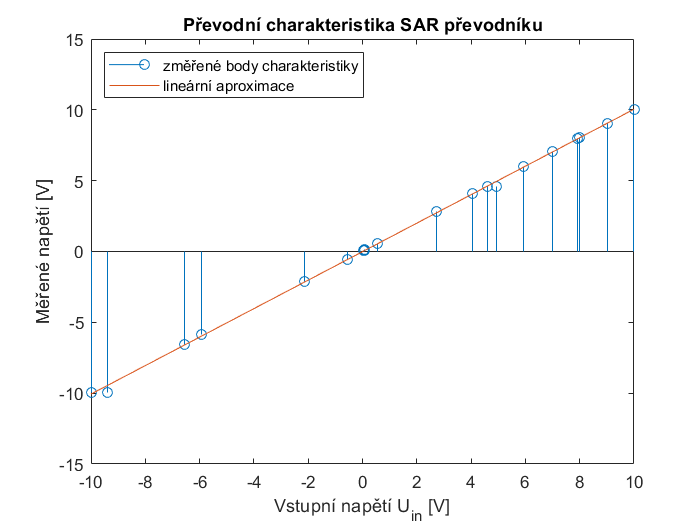

linAprox = poly2sym(linAprox);

expected = subs(linAprox, dataSet(:, 1));
stem(dataSet(:, 1), dataSet(:, 2));
hold on
plot(dataSet(:, 1), expected)
title('Převodní charakteristika SAR převodníku')
legend('změřené body charakteristiky', 'lineární aproximace', 'Location', 'northwest')
xlabel('Vstupní napětí U_{in} [V]')
ylabel('Měřené napětí [V]')

Změřená data vcelku skvěle odpovídají očekávanému průběhu s nějakou aditivní a multiplikativní chybou. Proložená lineární funkce má předpis $1.0054 x - 0.0099$, odtud je vidět $offset = -9.9$ mV a chyba zesílení $5.4 mV \cdot V^{-1}$. Jediné vychýlení od lineární aproximace je pro vstup $U_{in} \approx 5$V, kde je viditelný pokles převodní charakteristiky ve srovnání s očekáváním. Domnívám se, že se jedná o hrubou chybu, protože takové chování ADc nedává smysl. Jakmile něco nedává smysl, stojí za tím lidská chyba.

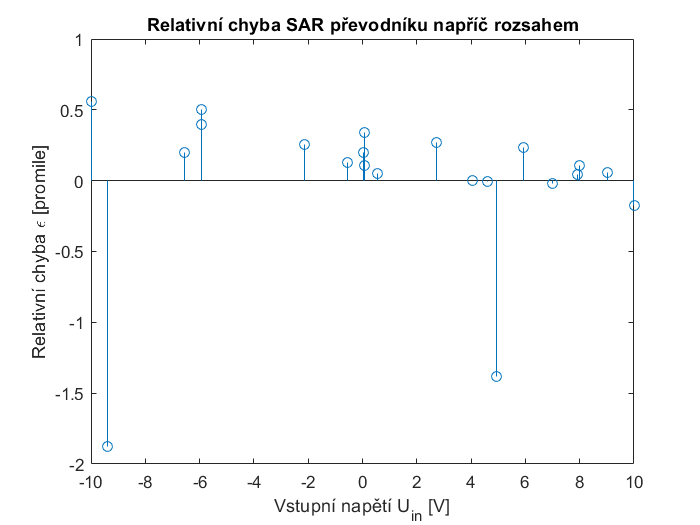

absError = dataSet(:, 2) - expected;
relError = absError / 256; %relativní vůči fullscale

figure
stem(dataSet(:, 1), relError * 1000); %na promile

title('Relativní chyba SAR převodníku napříč rozsahem')
xlabel('Vstupní napětí U_{in} [V]')
ylabel('Relativní chyba \epsilon [promile]')

### 2) Dual slope integration ADC

Převodník s dvojsklonnou integrací. Na obrázku je záznam osciloskopického sledování měřicího procesu takového ADC. Žlutý kanál je řídicí signál, který přepíná analogový mux mezi vstupní napětí $U_{in}$ a $U_{ref}$. Vysoká úroveň znamená, že se aktuálne integruje referenční napětí $U_{ref}$ a tedy že aktuálně běží odintegrovávací doba $T_2$. Na obrázku ADC měří vstupní napětí $U_{in} \approx  2$V.

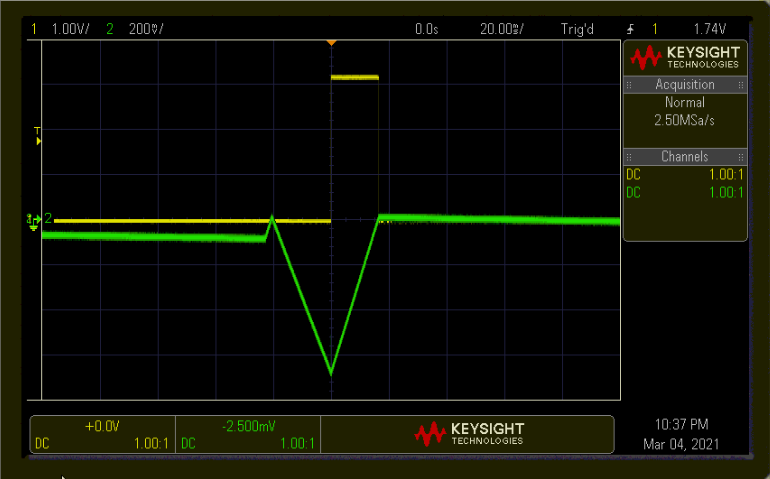

Pro srovnání následuje průběh integrace pro nižší napětí $U_{in} \approx 600$mV. Odintegrování je zřejmě kratší, první část trvá ale stejně stabilní dobu $T_1$.

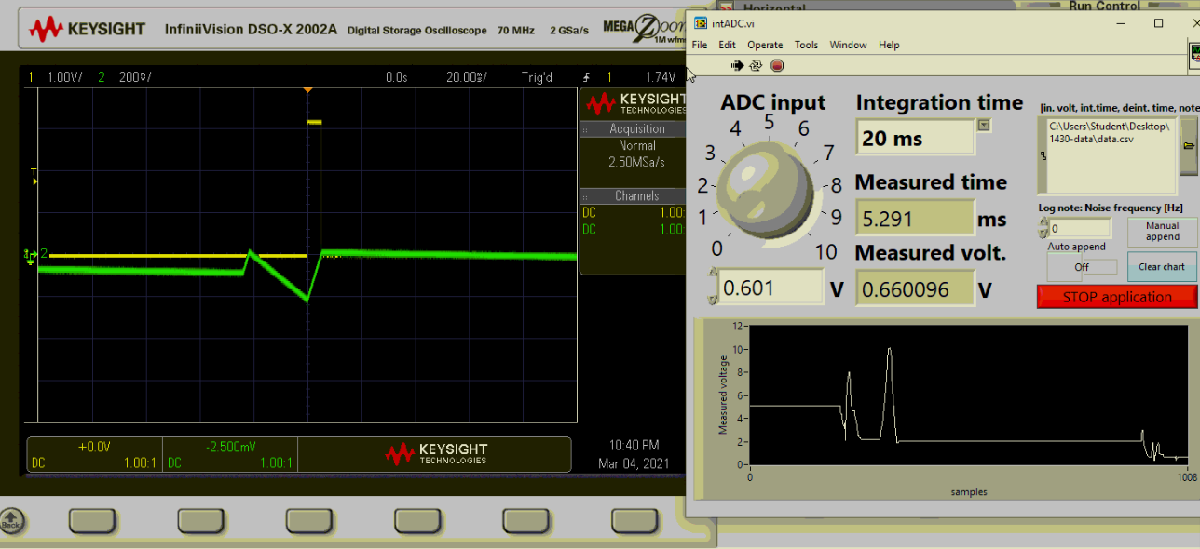 

Integrační převodníky jsou inherentně dobré na eliminaci rušení na známých frekvencích. Zvolí-li se příhodně doba integrace $T_1 = k \cdot T$, kde T je perioda harmonického rušení a $k \in \mathbb{N}$, poté měřený signál nebude danou frekvencí rušení zatážen, neboť se za dobu $T_1$ naintegruje celočíselný počet period, z nichž je integrál nulový.Toto je ilustrováno násleudjícím obrázkem, kde je zachycen měřený signál se superponovaným síťovým rušením.

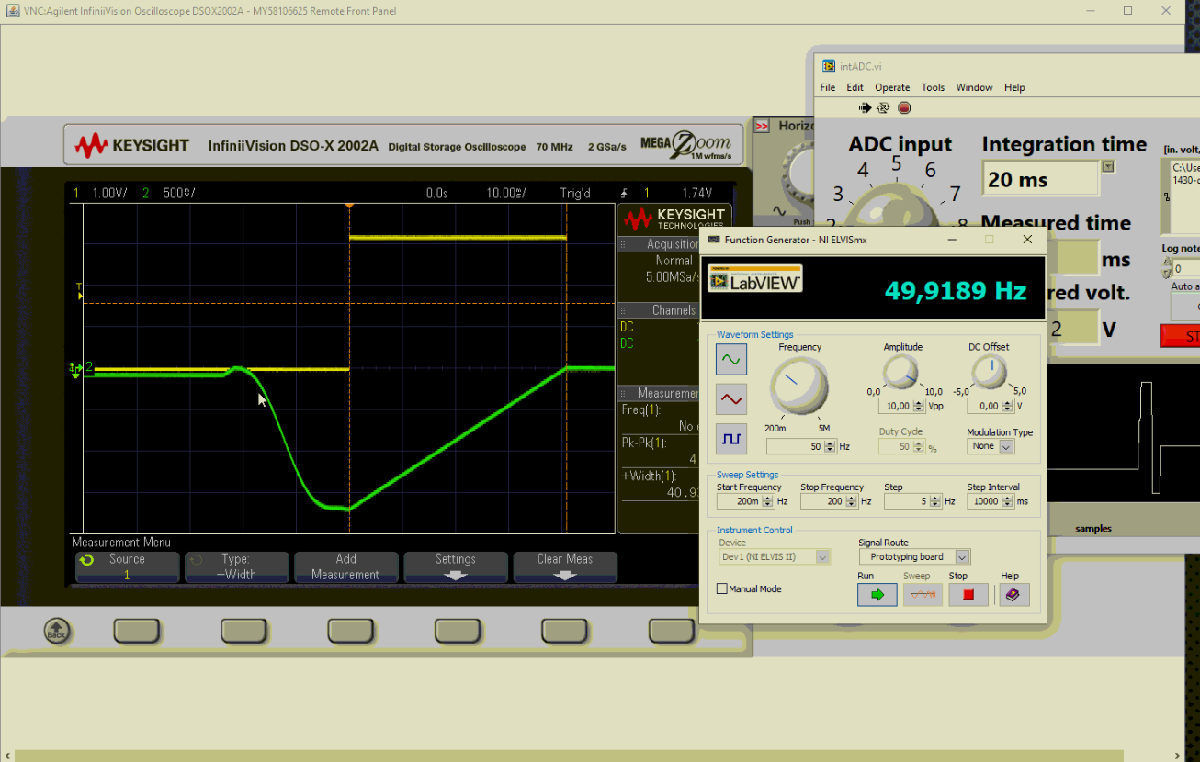

**Popis měření:** Měření provedeno na přípravku fakultní výbory sestaveném z mikrokontroleru STM32, analogového muxu a OP482 (JFETový operační zesilovač). Fullstale rozsah 0-10V, první část integrace má pevnou délku $T_1$ = 20ms, druhá část $T_2$ má proměnlivou délku. Z principu funkce převodníku je možné dosáhnout tak vysokého rozlišení, jak přesně lze měřit doby integrování signálu a následného odintegrovávání. Formát změřených dat: čtyři čísla ($U_{in}$, $T_1$, $T_2$, *dont care*) na řádek.

figure
dataInt = readmatrix('data/integracni/sweep.csv');
stem(dataInt(:, 1), dataInt(:, 3), 'filled')
linAprox = polyfit(dataInt(:,1), dataInt(:,3), 1)

linAprox =     8.0080    0.4606


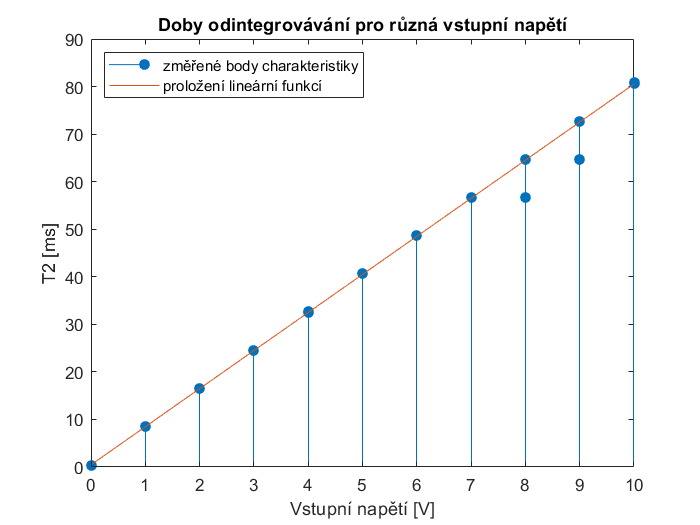

linAprox = poly2sym(linAprox); %Na proložení mi vychází linární funkce 8.008x + 0.46
hold on
plot(dataInt(:,1), subs(linAprox, dataInt(:, 1)))

title('Doby odintegrovávání pro různá vstupní napětí')
legend('změřené body charakteristiky', 'proložení lineární funkcí', 'Location', 'northwest');
xlabel('Vstupní napětí [V]')
ylabel('T2 [ms]')

V první řadě jsou vidět dvě velké deviace v měřených datech pro vstupní napětí 8 a 9 voltů. Pohledem na data lze zjistit, že se jedná o **chybu hrubou** způsobenou změnou vstupního napětí během procesu integrace. Vstupní napětí poté již bylo zaznamenáno nové, ale díky S&H obvodu na vstupu převodníku proběhl ještě převod starší (nižší) hodnoty za nižší čas. Protože se jedná jednoznačně o chyby hrubé, je možné je z datasetu prostě vyškrtnout. Žádná další znatelná vybočování charakteristiky z lineární oblasti nejsou na první pohled hotová, bude tedy nejspíše stačit vyšetřit offset a chybu zesílení.

% Odstranění hrubé chyby z dataInt
figure
inputs = dataInt(:, 1);
measured = dataInt(:, 3); %přejmenování setu změřených dat
expected = subs(linAprox, inputs); % data generovaná lineárním proložením
absError = measured - expected; % absolutní odchylka měřeného a očekávaného času T2 (v ms)

%Naše hrubé chyby představují skok o 8ms, odfiltruji tedy všechny hodnoty
%lišící se o víc jak 7ms.
validData = abs(absError) < 7;
inputs = inputs(validData);
measured = measured(validData);
expected = expected(validData);
absError = absError(validData);

linAprox = polyfit(inputs, measured, 1)

linAprox =     8.0355    0.4320


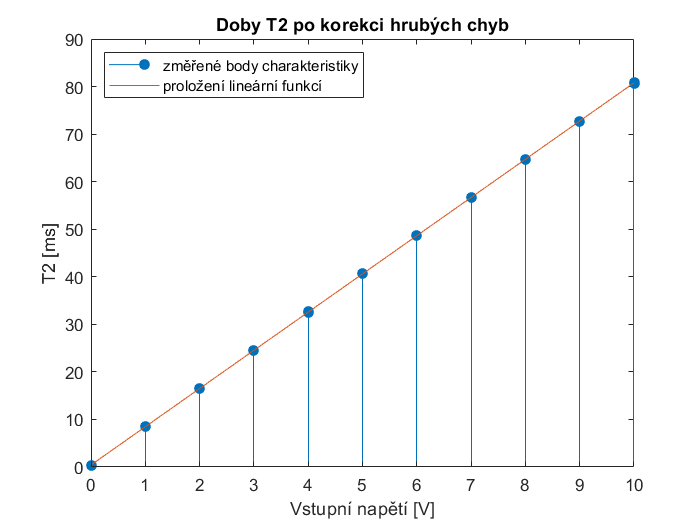

linAprox = poly2sym(linAprox); %Na proložení mi vychází linární funkce 8.0355x + 0.432
%Zajímavé je, že odstraněním hrubé chyby se zvýšila multiplikativní chyba.
% Lineární proložení mělo směrnici 8.008, nyní má 8.0355,
% je tedy vidět, že statisticky se chyby systematické s těmi hrubými částečně odečítaly.
%Odstraněné hrubé chyby byly menší než ideální hodnota a po jejich smazání
%chyba "zhrošila". Z toho plyne, že ostatní měřneé hodnoty mají tendenci být "větší" než
%je ideální hodnota. Z tohoto důvodu očekávám později zejména kladné relativní chyby.
stem(inputs, measured, 'filled')
hold on
plot(inputs, subs(linAprox, inputs))

title('Doby T2 po korekci hrubých chyb')
legend('změřené body charakteristiky', 'proložení lineární funkcí', 'Location', 'northwest');
xlabel('Vstupní napětí [V]')
ylabel('T2 [ms]')

Velikost vstupního napětí se počítá pomocí podílu dob T1 a T2 jako $U_{in} = U_{ref}\frac{T_2}{T_1}$. Protože známe nastavení doby $T_1$ = 20ms, lze pomocí změřených dat a proložené lineární závislosti snadno určit, že **interní napěťová reference ADC** je $U_{ref} = 2.5$V. Dosazením hodnot $U_{ref}$ a $T_1$ do obecného vztahu pro $U_{in}
$ získáme vztah $T_2 = T_1 \frac{U_{in}}{U_{ref}} = U_{in} \frac{20ms}{2.5 V} = U_{in} \cdot 8 [ms \cdot V^{-1}]$. Tento vztah budu dále považovat za **ideální převodní charakteristiku**, vůči které bude potřeba nalézt chybu zesílení a konstantní offset reálného měřicího zařízení. 

**Aditivní a multiplikativní chybu **převodní charakteristiky ADC nalezl již Matlab funkcí polyfit. Pro ruční výpočet offsetu a chyby gainu je potřeba nejprve nalézt aditivní chybu a jejím odečtením posunout celou charakteristiku do nuly pro nulové napětí na vstupu (měření země). Nejrozumnější pro nalezení offsetu je vzít průměr měřených časů $T_2$, když byl na vstupu nulový potenciál:

inputIsZero = inputs == 0;
gndMeas = dataInt(inputIsZero, :); % všechna měření, kde na vstupu byla nula

offset = mean(gndMeas(:, 3)) %Vychází 0.4091 milisekund

offset = 0.4091

Tento offset je ale odlišný od offsetu nalezeného funkcí polyfit výše, proto je jasné, že převodní charakteristika bude mít i nelineární prvek! Nalezněme velikost relativních odchylek reálného převodníku od lineárního proložení:

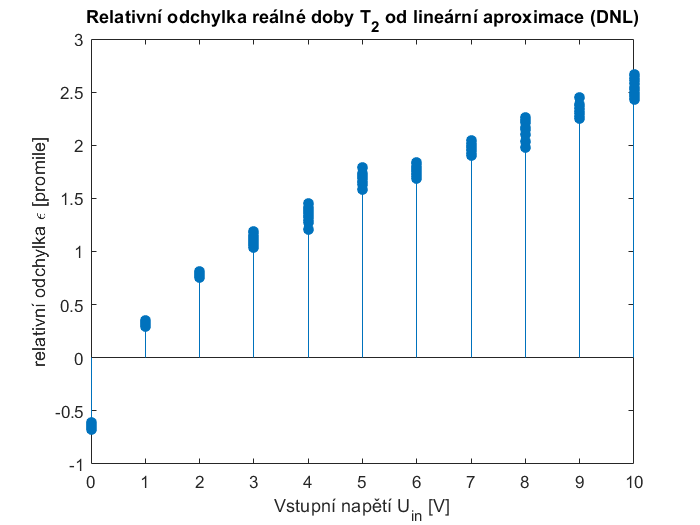

relError = absError / subs(linAprox, 10); % a táž chyba, jen relativně.

figure;
stem(inputs, relError * 1000, 'filled'); %Chybu vyneseme v promile
title('Relativní odchylka reálné doby T_2 od lineární aproximace (DNL)');
xlabel('Vstupní napětí U_{in} [V]')
ylabel('relativní odchylka \epsilon [promile]')